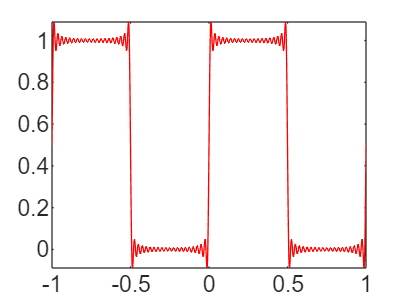

clear
clf

% Basic konstanter
T = 1;
Tp = 0.5;
t = -T:0.001:T;
N = 40;
k = (-N:N)';
omegak = 2*pi/T*k;
F = exp(1i*omegak*t);

% Kvadratvåg
Xk = Tp/T*exp(-1i*omegak*Tp/2).*(sin(omegak*Tp/2)./(omegak*Tp/2));
zeroindex = k==0;
Xk(zeroindex) = Tp/T;

xk = real(Xk.'*F);

figure(1)
plot(t, xk, 'r-')

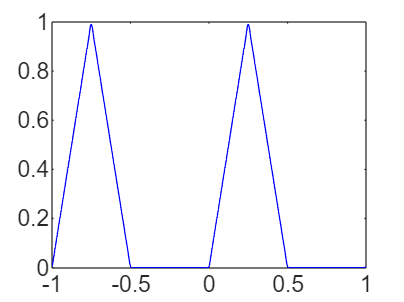


% Triangelvåg
Xt = exp(-1i*omegak*Tp/2).*((-4/Tp)*(cos(omegak*Tp/2)-1)./(omegak.*omegak));
zeroindex = find(k==0);
Xt(zeroindex) = Tp/2;

xt = real(Xt.'*F);

figure(2)
plot(t, xt, 'b-')

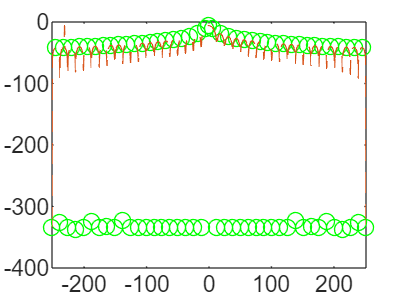


% Kvadratpuls fouriertransform
omega = linspace(omegak(1), omegak(end), 1000);
XkF = Tp/T*exp(-1i*omega*Tp/2).*(sin(omega*Tp/2)./(omega*Tp/2));
zeroindex2 = k==0;
XkF(zeroindex2) = Tp/T;

figure(3)
plot(omegak, 20*log10(abs(Xk)), 'go')
hold on
plot(omega, 20*log10(abs(XkF)), '--')
hold off